## 21052105Display a hot air ballon

## Display chalks

#### R G B seperation

`I=imread(``'image.jpg'``)`

will give I (a 3d array, of size [x,y,3] )where x and y are the dimensions of the image. 3 is for R, G, and B components.

Download Img Processing Package.

To separate out the three components, you can do -> 

In this, we'll separate the RGB image and combine RG, BG, RB together to form di-tonic images.

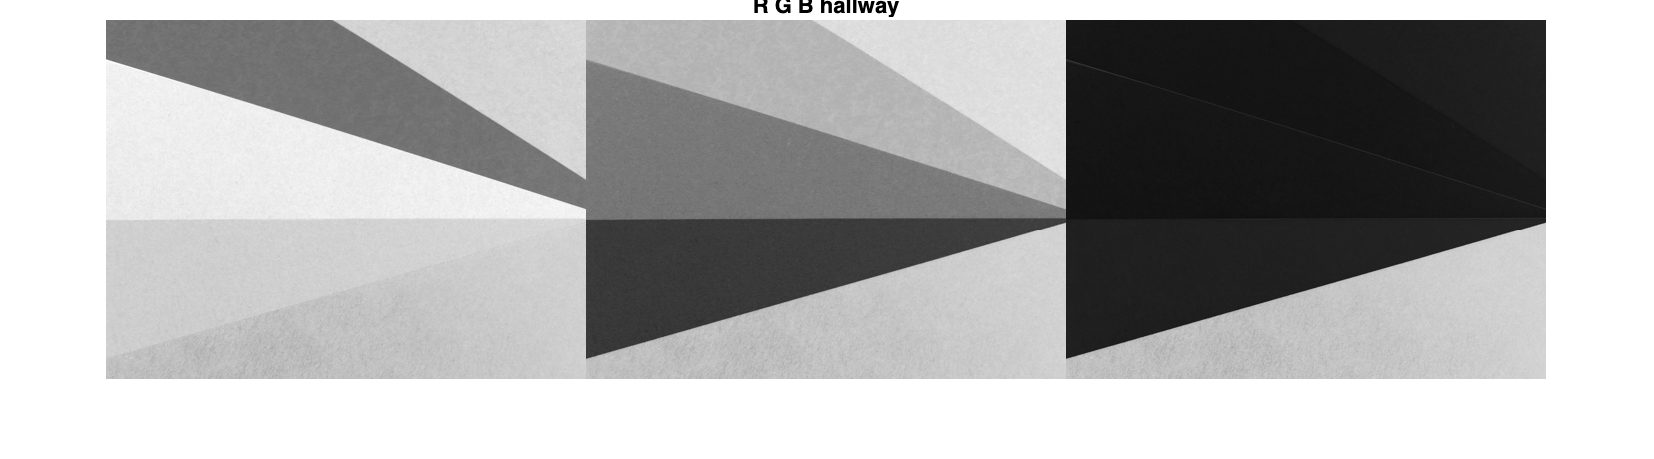

I_2 = imread('raw_images/color_bands.jpg');
% imshow(I_2);
heading = "hallway";
title(heading);
[R_2, G_2, B_2] = imsplit(I_2);
montage({R_2,G_2,B_2},'Size',[1 3]);
title("R G B " + heading);

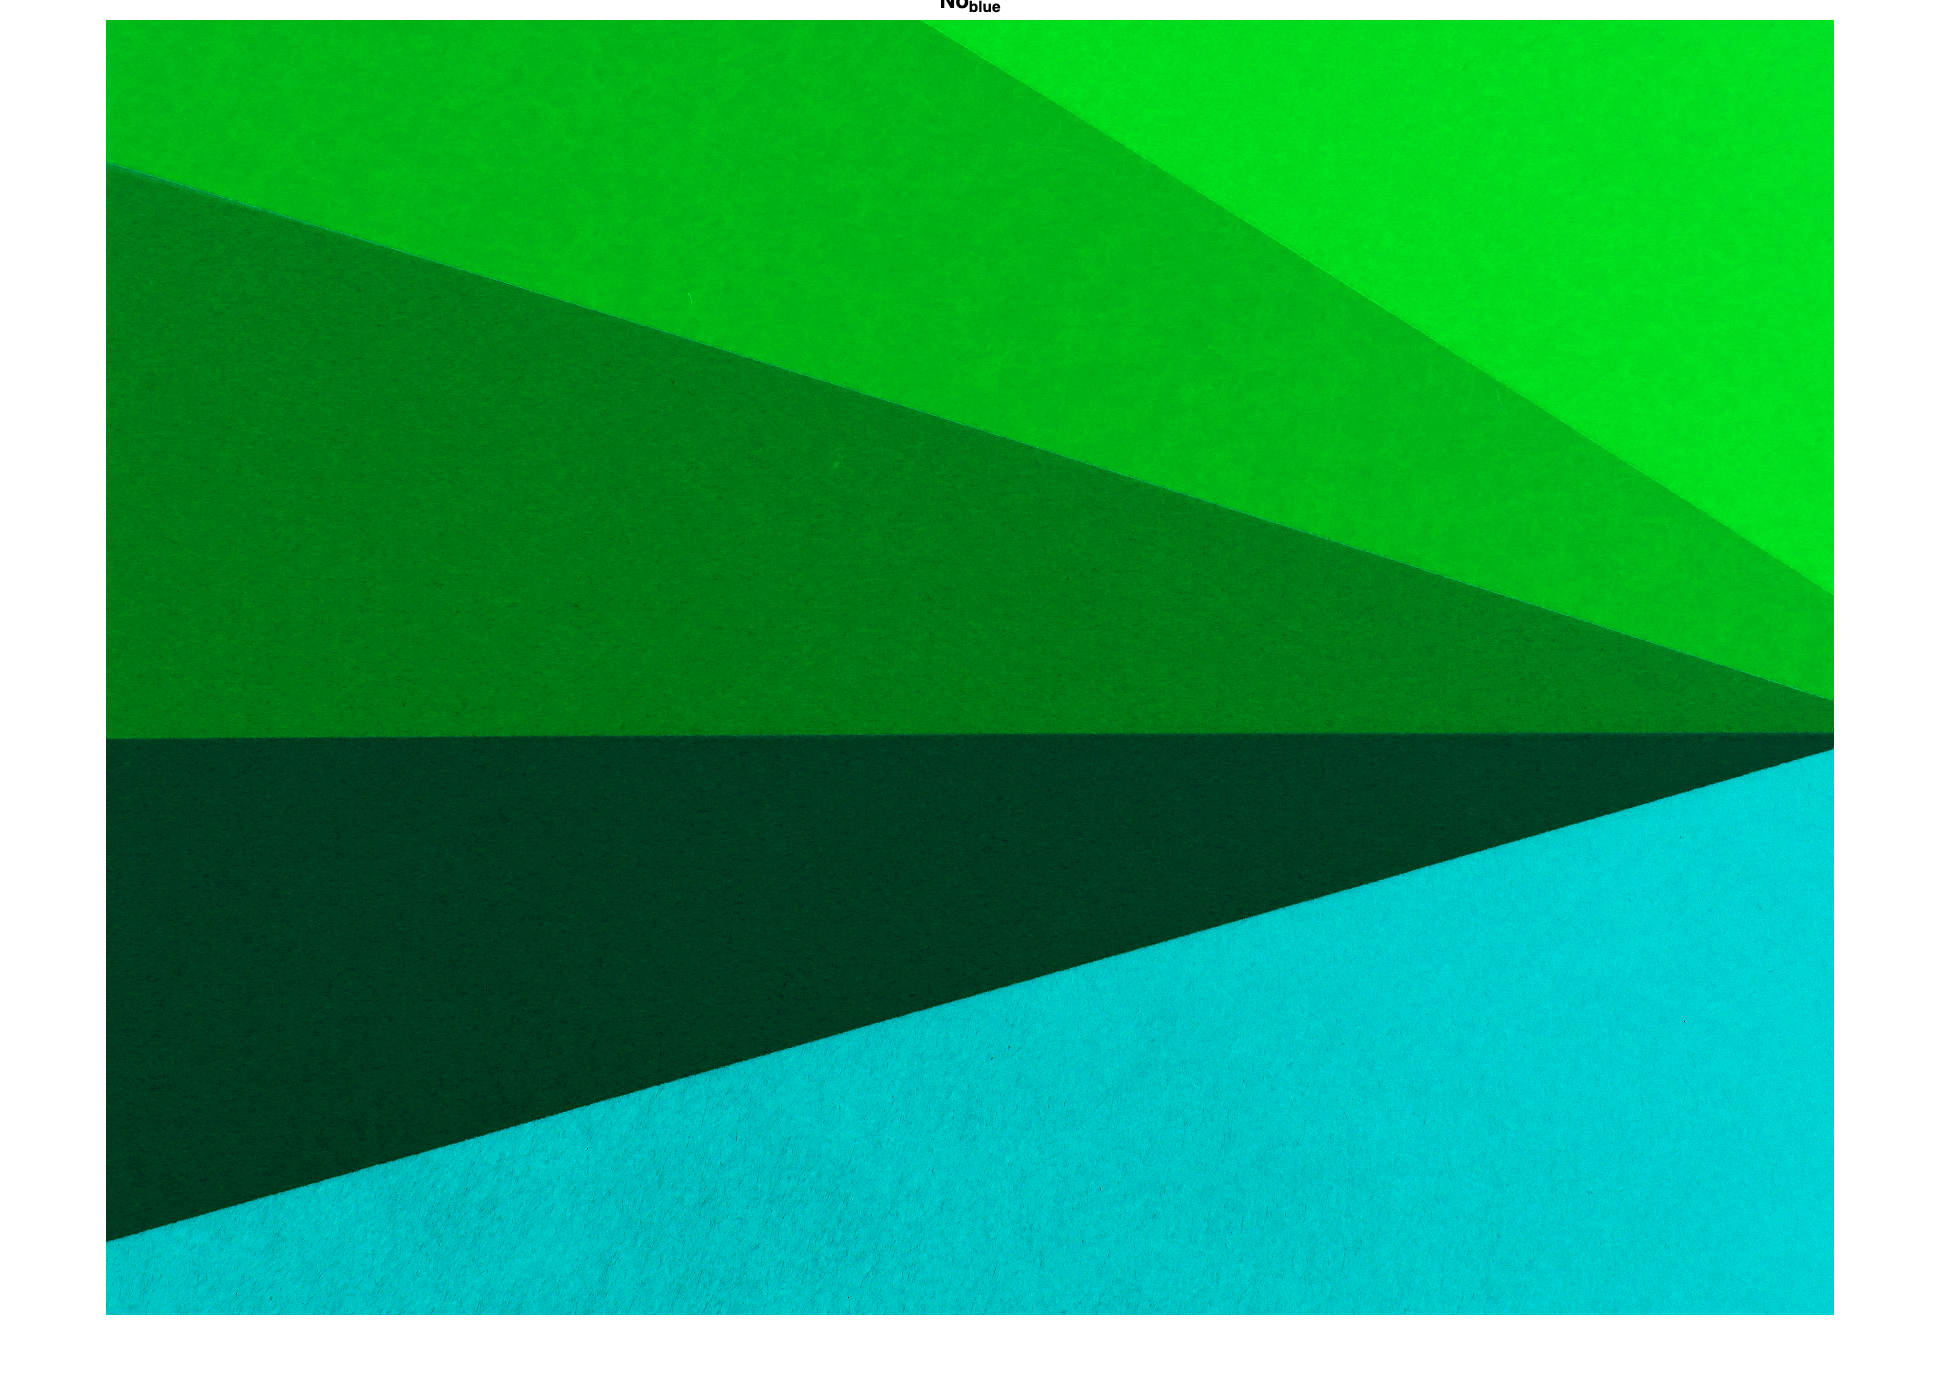

% seperated R G B values%
redChannel = I_2(:, :, 1);
greenChannel = I_2(:, :, 2);
blueChannel = I_2(:, :, 3);

% setting R value to 0 %
redChannel = zeros(size(redChannel));
gbImage = cat(3, redChannel, greenChannel, blueChannel);
imshow(gbImage);
title("No_red");
% seperated R G B values%
redChannel = I_2(:, :, 1);
greenChannel = I_2(:, :, 2);
blueChannel = I_2(:, :, 3);

% setting G value to 0 %
greenChannel = zeros(size(greenChannel));
rbImage = cat(3, redChannel, greenChannel, blueChannel);
% imshow(rbImage);
title("No_green");
% seperated R G B values%
redChannel = I_2(:, :, 1);
greenChannel = I_2(:, :, 2);
blueChannel = I_2(:, :, 3);

% setting B value to 0 %
blueChannel = zeros(size(blueChannel));
rgImage = cat(3, redChannel, greenChannel, blueChannel);
% imshow(rgImage);
title("No_blue");

### Flipping the Image.

flippedImage = fliplr(redChannel); % flipped matrix of the image.
% imshow(flippedImage); 

% selecting one color channel
% imshow(redChannel);
% subtracting flipped image from image.

% subtracted_image = redChannel - flippedImage; 
% subtracted_image = abs(subtracted_image)
% imshow((subtracted_image))


% finding the laterality of the image by inversing the intensity of the
% image.

% inversedI_2 = imcomplement(subtracted_image);
% imshow(inversedI_2)
% montage({subtracted_image, redChannel, flippedImage},'Size',[1 3]);
a = [243,100;50,2]

a =    243   100
    50     2


flippedImage = fliplr(a);
subA = a - flippedImage;
subA = abs(subA)

subA =    143   143
    48    48


testImg = imread('raw_images/colored_chalks.jpg')

testImg = 3744×5616×3 uint8 array
testImg(:,:,1) =

  Columns 1 through 5,461

     2     2     2     2     2     2     2     2     0     0     0     0     0     0     0     0     2     2     1     1     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     1     1     1     1     1     1     1     1     1     1     2     2     2     0     0     0     0     0     0     0     0     1   

fImg = redChannel - testImg(0:3887, 0:5183, 1);

Index in position 1 is invalid. Array indices must be positive integers or logical values.

imshow(fImg);